Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Equilibrium of a Robinson-Crusoe economy (Section 11.1)

Volker Ziemann, 211116, CC-BY-SA-4.0

In this example we explore the equilibrium state of a Robinson-Crusoe economy, which given the stationary solution of the Bellman equation for this system given by Equation 11.9. The dependence of the equilibrium capital $\bar k$ and profit $\bar p$ on the depecration $\delta$ and the technological level $\lambda$ is given in Equation 11.11, which also leads to the plots in Figure 11.2. 

We start out by defining the parameters discount factor `beta,` the technological level `lambda,` and the Cobb-Douglas parameter `Theta` of the simulation.

clear all
beta=0.8;    % care about the future
lambda=1;   % technology level
Theta=0.7;                         % Cobb-Douglas parameter

Next we specify the range of values for the **deprecation** `delta` that we want to explore and use the function `optim(),` defined in the Appendix, to determine the equilibrium capital `kbar`, the profit `pbar` and the investment `ibar.`

delta=0.1:0.01:0.5;
[kbar,pbar,ibar]=optim(beta,delta,lambda,Theta);

Having all interesting quantities available we proceed to plot them and annotate the axes.

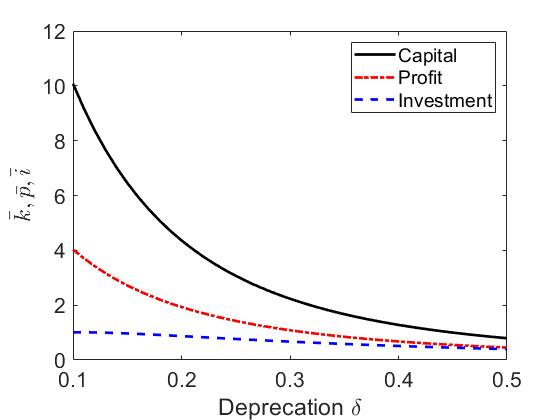

plot(delta,kbar,'k',delta,pbar,'r-.',delta,ibar,'b--','LineWidth',2)
xlabel('Deprecation \delta'); 
ylabel('$\bar k, \bar p, \bar i$','Interpreter','Latex')
legend('Capital','Profit','Investment')
set(gca,'FontSize',16)

One conclusion from this plot is immediate; it pays off to take good care of one's investment, for example by buying high-quality machinery and maintaining it well. In this case capital does not deprecate  so quick and $\delta$ is small, which leads to high values for the capital and, important for the investors, to high profits, shown as the red line.

In the second example we look at the equilibrium values for capital `kbar` and profit `pbar` as a function of the **technological level **`lambda`. We first select the deprecation delta and specify the range of lambda to explore and calculate the equilibrium values with optim() before plotting them.

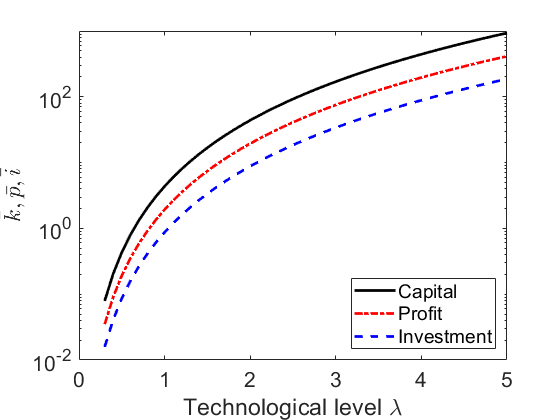

delta=0.2;  % choose deprecation
lambda=0.3:0.1:5;                 % range of technological levels
[kbar,pbar,ibar]=optim(beta,delta,lambda,Theta);
figure; semilogy(lambda,kbar,'k',lambda,pbar,'r-.',lambda,ibar,'b--','LineWidth',2)
xlabel('Technological level \lambda'); 
ylabel('$\bar k, \bar p, \bar i$','Interpreter','Latex')
legend('Capital','Profit','Investment','Location','SouthEast')
set(gca,'FontSize',16)

Note the logarithmic scale on the vertical axis, which makes it obvious that a high technological level, which translates into a high output per unit invested capital, is essential to maintain a large capital $\bar k$ and corresponding profit $\bar p$.

## Appendix

The function `optim()` receives as input the discount parameter `beta`, the deprecation `delta`, the technological level `lambda`, and the Cobb-Douglas parameter `Theta`. It then uses Equations 11.11 to calculate the equilibrium capital `kbar`, the profits `pbar`, and the investment `ibar`.

function [kbar,pbar,ibar]=optim(beta,delta,lambda,Theta)
kbar=((1/beta-1+delta)./(lambda.*Theta)).^(1./(Theta-1));
pbar=lambda.*kbar.^Theta-delta.*kbar;
ibar=delta.*kbar;
end